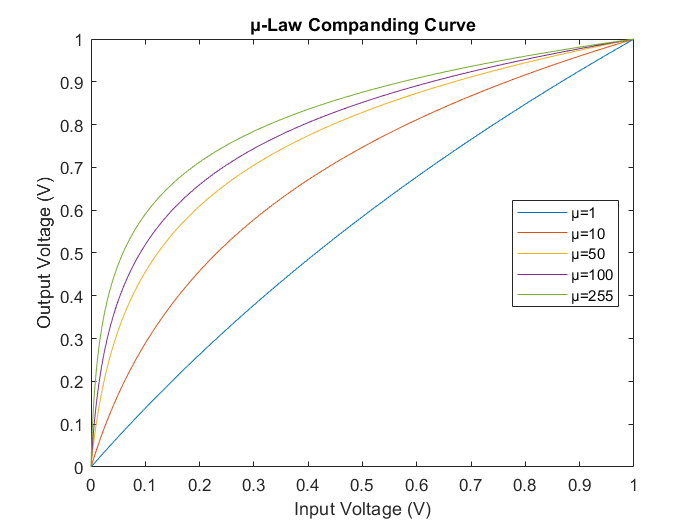

% Define the input voltage range
Vin = linspace(0, 1, 1000);

% Define the mu values to plot
mu_values = [1, 10, 50, 100, 255];

% Loop over the μ values and calculate the output voltage for each one
for i = 1:length(mu_values)
    mu = mu_values(i);
    
    Vout = sign(Vin) .* log(1 + mu*abs(Vin)) ./ log(1 + mu);
    
    % Plot the output voltage vs input voltage for the current mu value
    plot(Vin, Vout);
    hold on;
end

% Add axis labels and a title
xlabel('Input Voltage (V)');
ylabel('Output Voltage (V)');
title('μ-Law Companding Curve');

% Add a legend
legend('μ=1', 'μ=10', 'μ=50', 'μ=100', 'μ=255',"Location","best");